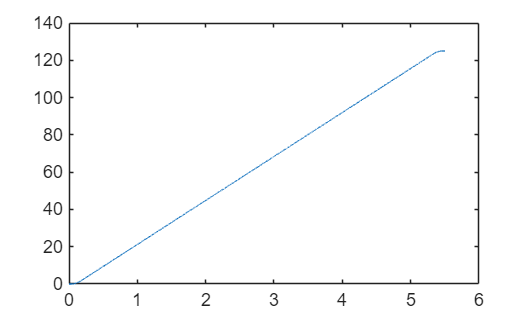


y   = 125;     % total move [m]
T   = 11/2;      % total time [s]
y_a = 2.4;     % distance at which you want constant velocity to begin [m]
dt  = 1/4000;      % sample time [s]

[t, yref, vref, aref, jref, P] = s3_fast_ref(y, T, y_a, dt);

figure; plot(t,yref);

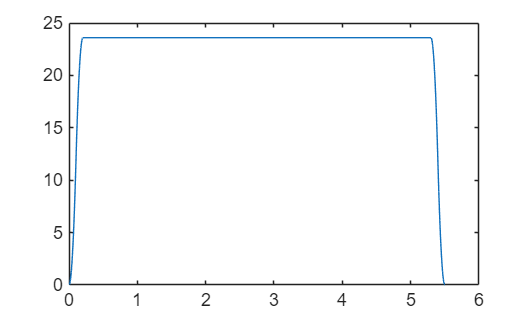

figure; plot(t,vref);

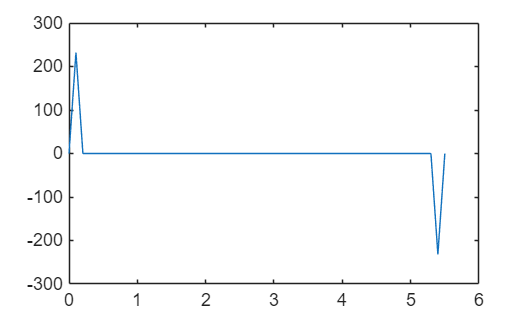

figure; plot(t,aref);

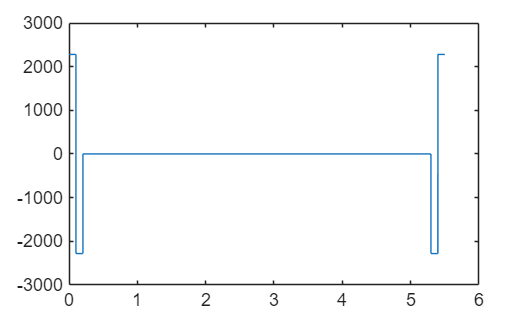

figure; plot(t,jref);


% jref, aref, vref are what you feed into your ref3 generator
% sanity check:
fprintf('v_max = %.6f, A = %.6f, J = %.6f, tS = %.6f, tC = %.6f\n', ...
    P.v_max, P.A, P.J, P.tS, P.tC);

v_max = 23.600000, A = 232.066667, J = 2281.988889, tS = 0.203390, tC = 5.093220



function [t, y_out, v, a, j, param] = s3_fast_ref(y, T, y_a, dt)
% s3_fast_ref  Fastest symmetric 3rd-order (jerk-limited) setpoint generator
%   Ensures: at y = y_a the motion is at constant velocity (a = 0),
%   total move y in total time T, start/end at rest.
%
%   Inputs
%     y    : total distance (>0)
%     T    : total time (>0)
%     y_a  : distance at which constant-velocity starts (0 <= y_a <= y/2)
%     dt   : sample time (optional, default = T/2000)
%
%   Outputs
%     t       : time stamps [1xN]
%     y_out   : position profile [1xN]
%     v       : velocity profile [1xN]
%     a       : acceleration profile [1xN]
%     j       : jerk profile [1xN]
%     param   : struct with fields v_max, A, J, tS, tj, tC
%
%   Segments (symmetric):
%     1) jerk +J for t_j       (accel ramps 0 -> +A)
%     2) jerk -J for t_j       (accel ramps +A -> 0), reach v_max at y = y_a
%     3) cruise for t_C        (a=0, j=0, v=v_max)
%     4) jerk -J for t_j       (accel 0 -> -A)
%     5) jerk +J for t_j       (accel -A -> 0), stop at y
%
%   Notes
%     Exact (per-segment) kinematics are used, not Euler integration,
%     so you can use coarse dt without accumulating drift.

    arguments
        y   (1,1) double {mustBePositive}
        T   (1,1) double {mustBePositive}
        y_a (1,1) double {mustBeNonnegative}
        dt  (1,1) double {mustBePositive} = T/2000
    end

    % Feasibility checks
    if y_a > y/2 + 1e-12
        error('Infeasible: need y_a <= y/2 for a nonnegative cruise time.');
    end

    % Solve timing and limits
    tS   = (2*y_a*T) / (y + 2*y_a);       % time of one S-curve (accel up+down)
    tj   = tS/2;                           % single jerk half
    tC   = T - 2*tS;                       % cruise time (>=0)
    vMax = (y + 2*y_a)/T;                  % constant velocity level
    A    = (2*vMax)/tS;                    % peak acceleration
    J    = (4*vMax)/(tS^2);                % jerk magnitude

    % Time vector
    N  = max(2, ceil(T/dt)+1);
    t  = linspace(0, T, N);

    % Segment boundaries
    t1 = tj;
    t2 = 2*tj;
    t3 = 2*tj + tC;
    t4 = 3*tj + tC;
    t5 = 4*tj + tC; % == T

    % Preallocate
    a = zeros(1,N);
    v = zeros(1,N);
    y_out = zeros(1,N);
    j = zeros(1,N);

    % Helper: exact constant-jerk update from (a0,v0,y0) over local time tau
    %   a = a0 + Jc*tau
    %   v = v0 + a0*tau + 0.5*Jc*tau^2
    %   y = y0 + v0*tau + 0.5*a0*tau^2 + (1/6)*Jc*tau^3
    function [a1,v1,y1] = step_const_jerk(a0,v0,y0,Jc,tau)
        a1 = a0 + Jc.*tau;
        v1 = v0 + a0.*tau + 0.5*Jc.*tau.^2;
        y1 = y0 + v0.*tau + 0.5*a0.*tau.^2 + (1/6)*Jc.*tau.^3;
    end

    % March through segments analytically
    a0 = 0; v0 = 0; y0 = 0;

    % Segment 1: 0..t1, j=+J
    idx = t <= t1 + eps;
    tau = t(idx) - 0;
    j(idx) = +J;
    [a(idx), v(idx), y_out(idx)] = step_const_jerk(a0,v0,y0,+J,tau);
    % End-of-seg state:
    a1e = A; v1e = vMax/2; y1e = y_out(find(idx,1,'last'));

    % Segment 2: t1..t2, j=-J
    idx = (t > t1-eps) & (t <= t2 + eps);
    tau = t(idx) - t1;
    j(idx) = -J;
    [a(idx), v(idx), y_out(idx)] = step_const_jerk(a1e,v1e,y1e,-J,tau);
    % End-of-seg state (at constant velocity start, position = y_a):
    a2e = 0; v2e = vMax; y2e = y_out(find(idx,1,'last'));  %#ok<FNDSB>

    % Segment 3: t2..t3, cruise (j=0, a=0, v=vMax)
    idx = (t > t2-eps) & (t <= t3 + eps);
    tau = t(idx) - t2;
    j(idx) = 0;
    a(idx) = 0;
    v(idx) = v2e;
    y_out(idx) = y2e + v2e.*tau;
    % End-of-seg state:
    a3e = 0; v3e = vMax; y3e = y_out(find(idx,1,'last'));

    % Segment 4: t3..t4, j=-J (mirror of seg2)
    idx = (t > t3-eps) & (t <= t4 + eps);
    tau = t(idx) - t3;
    j(idx) = -J;
    [a(idx), v(idx), y_out(idx)] = step_const_jerk(a3e,v3e,y3e,-J,tau);
    % End-of-seg state:
    a4e = -A; v4e = vMax/2; y4e = y_out(find(idx,1,'last'));

    % Segment 5: t4..t5, j=+J (mirror of seg1)
    idx = (t > t4-eps);
    tau = t(idx) - t4;
    j(idx) = +J;
    [a(idx), v(idx), y_out(idx)] = step_const_jerk(a4e,v4e,y4e,+J,tau);

    % Numerical tidy-up at the very end
    y_out(end) = y;
    v(end) = 0;
    a(end) = 0;

    % Pack parameters
    param.v_max = vMax;
    param.A     = A;
    param.J     = J;
    param.tS    = tS;
    param.tj    = tj;
    param.tC    = tC;
end
